**The simulations depicting the temporal changes after acute depletion of Xrn1.**

**For Figure 4a, b, and S6.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

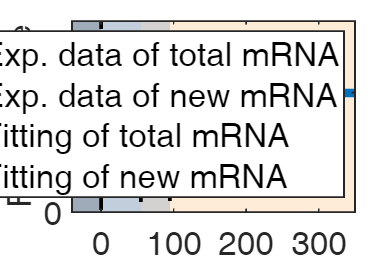

para0=para_opt;

% Symbolic solutions
load ../Solve_values/Solve_values.mat
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];


% Simulations
[kn_wt,kn_tot,y_wt,y_tot]=Xcdeplete_noFC(para0,syms_solve);
%y:[mn mc Xn Xc Xp Yn Yp]
%temp_mn=y_tot(:,1)/y_wt(1);
%temp_mc=y_tot(:,2)/y_wt(2);
temp_m=(y_tot(:,1)+y_tot(:,2))/(y_wt(1)+y_wt(2));
%temp_Xn=y_tot(:,3)/y_wt(3);
temp_Xc=y_tot(:,4)/y_wt(4);
temp_Xp=y_tot(:,5)/y_wt(5);
%temp_Yn=y_tot(:,6)/y_wt(6);
%temp_Yp=y_tot(:,7)/y_wt(7);
temp_kn=kn_tot/kn_wt;

cmFC=temp_m';
knFC=temp_kn;


%%% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


% Experimental data and the fitting (Figure 4a)

% Data
Data_Chappleboim2022_xrn1=readmatrix('..\Data\Data_Chappleboim2022.xlsx','sheet','xrn1');


fig=figure;
set(fig,'Position',[300 100 1000 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


rectangle('Position',[-50,-1,50,3], ...
    'EdgeColor','none', ...
    'FaceColor',[159,171,185]/255);
hold on
rectangle('Position',[0,-1,55,3], ...
    'EdgeColor','none', ...
    'FaceColor',[194,206,220]/255);
hold on
rectangle('Position',[55,-1,40,3], ...
    'EdgeColor','none', ...
    'FaceColor',[211,210,208]/255);
hold on
rectangle('Position',[95,-1,400,3], ...
    'EdgeColor','none', ...
    'FaceColor',[254,236,216]/255);
hold on
plot([0,0],[-1,3],'--', ...
    "Color",'black', ...
    "LineWidth",2)
hold on
plot([55,55],[-1,3],'--', ...
    "Color",'black', ...
    "LineWidth",2)
hold on
plot([95,95],[-1,3],'--', ...
    "Color",'black', ...
    "LineWidth",2)
hold on


scale_time=1:1000;
temp1=[ones(1,100),cmFC];
temp2=[-100:1:-1,scale_time];
p5=plot(temp2,temp1,'--', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","Fitting of total mRNA");
hold on
temp1=[ones(1,100),knFC];
temp2=[-100:1:-1,scale_time];
p6=plot(temp2,temp1,'--', ...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Fitting of new mRNA");
hold on
p1=plot(Data_Chappleboim2022_xrn1(:,1),Data_Chappleboim2022_xrn1(:,2), ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(10), ...
    "DisplayName","Exp. data of total mRNA");
hold on
p2=plot(Data_Chappleboim2022_xrn1(:,1),Data_Chappleboim2022_xrn1(:,3), ...
    '^', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(8), ...
    "DisplayName","Exp. data of new mRNA");
hold off
xlim([-40,350])
ylim([0,1.6])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
set(gca,'Layer','top')
box(gca,'on')
legend([p1 p2 p5 p6],"Interpreter","tex","FontSize",20)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);

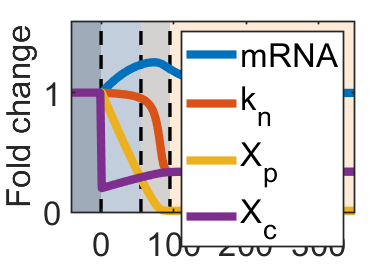




% Simulations (Figure 4b)

fig=figure;
set(fig,'Position',[300 100 1000 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);

rectangle('Position',[-50,-1,50,3], ...
    'EdgeColor','none', ...
    'FaceColor',[159,171,185]/255);
hold on
rectangle('Position',[0,-1,55,3], ...
    'EdgeColor','none', ...
    'FaceColor',[194,206,220]/255);
hold on
rectangle('Position',[55,-1,40,3], ...
    'EdgeColor','none', ...
    'FaceColor',[211,210,208]/255);
hold on
rectangle('Position',[95,-1,400,3], ...
    'EdgeColor','none', ...
    'FaceColor',[254,236,216]/255);
hold on
plot([0,0],[-1,3],'--', ...
    "Color",'black', ...
    "LineWidth",2)
hold on
plot([55,55],[-1,3],'--', ...
    "Color",'black', ...
    "LineWidth",2)
hold on
plot([95,95],[-1,3],'--', ...
    "Color",'black', ...
    "LineWidth",2)
hold on

scale_time=1:1000;
temp1=[ones(100,1);temp_m];
temp2=[-100:1:-1,scale_time];
p1=plot(temp2,temp1, ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","mRNA");
hold on

temp1=[ones(1,100),temp_kn];
temp2=[-100:1:-1,scale_time];
p2=plot(temp2,temp1, ...
    'DisplayName',"k_n", ...
    "Color",colors(2),...
    "LineWidth",5);

hold on

temp1=[ones(100,1);temp_Xp];
temp2=[-100:1:-1,scale_time];
p3=plot(temp2,temp1, ...
    'DisplayName',"X_p", ...
    "Color",colors(3),...
    "LineWidth",5);
hold on

temp1=[ones(100,1);temp_Xc];
temp2=[-100:1:-1,scale_time];
p4=plot(temp2,temp1, ...
    'DisplayName',"X_c", ...
    "Color",colors(4),...
    "LineWidth",5);
hold off
xlim([-40,350])
ylim([0,1.6])

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
set(gca,'Layer','top')
box(gca,'on')
legend([p1 p2 p3 p4],"Interpreter","tex","FontSize",20)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);

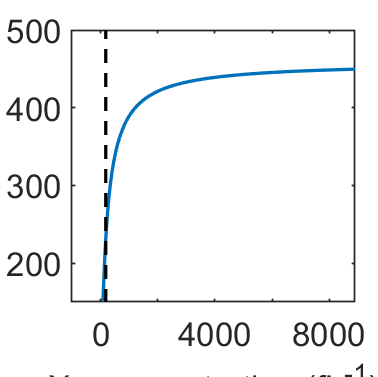




% The relationship between Xp and kn (Figure S6)

Vn=2.8;
temp_Xp=y_tot(:,5)/Vn;
temp_kn=kn_tot;

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(temp_Xp,temp_kn, ...
    "LineWidth",2, ...
    "Color",colors(1),...
    "DisplayName","Experiments of $c_m$ when depleting Xrn1");
hold on
plot([para0(2),para0(2)],[150,600],'--', ...
    "LineWidth",2, ...
    "Color",'black');

hold off

xlim([-1000,8900])
ylim([150,500])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('X_p concentration (fL^{-1})','interpreter','tex','FontSize',20);
ylabel('mRNA production rate (min^{-1})','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
Kv=5.8262;%fL
k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);


dydt = zeros(7,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt]

Vn=2.8;%fL
Vc=37.2;%fL

kn=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



function [kn_wt,kn_tot,y_wt,y_tot]=Xcdeplete_noFC(para0,syms_solve)
%%% The function calculating the values of molecules.

%Numerically solve the values of molecules in WT cells
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0,2.8,37.2,5.8262];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc

y_wt=[temp2,temp1];


%paramters
Kv=5.8262;%fL
k0=para0(1);
Kx=para0(2);
Ky=para0(3);
Km=para0(4);
%am=para0(5);
%ax=para0(6);
%ay=para0(7);
%bm=para0(8);
%bx=para0(9);
%Xt=para0(10);
%Yt=para0(11);
mn=y_wt(1);
%mc=y_wt(2);
%Xn=y_wt(3);
%Xc=y_wt(4);
Xp=y_wt(5);
%Yn=y_wt(6);
Yp=y_wt(7);
Vn=2.8;%fL
%Vc=37.2;%fL

kn_wt=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

y_ini=y_wt;
y_ini(3)=y_ini(3);
y_ini(4)=y_ini(4)*0.2; %Deplete 80% of Xc
y_ini(5)=y_ini(5);

%Calculate the values of molecules after depletion
tspan=[1:1:1000];
[~,y_tot]=ode15s(@(t,y)diffun(y,para0),tspan,y_ini);

%Calculate the kn after depletion
kn_tot=zeros(1,length(tspan));
for i=1:length(tspan)
    mn=y_tot(i,1);
    %mc=y_tot(i,2);
    %Xn=y_tot(i,3);
    %Xc=y_tot(i,4);
    Xp=y_tot(i,5);
    %Yn=y_tot(i,6);
    Yp=y_tot(i,7);
    kn_tot(i)=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);
end


end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

